Laboratorium 1

Przypomnienie podstaw środowiska Matlab oraz podstaw przetwarzania sygnałów.

Zad 1

Rozwiąż układ równań

x+2y+3z=1

4x+5,5y+6z=1

7x+8y+9,5z=1

syms x y z;

eqn1 = x + 2*y + 3*z == 1;
eqn2 = 4*x + 5.5*y + 6*z == 1;
eqn3 = 7*x + 8*y + 9.5*z == 1;

[A,B] = equationsToMatrix([eqn1, eqn2, eqn3], [x, y, z]);
X = linsolve(A, B);
X

$$X = \left(\begin{array}{c} -\frac{19}{29}\\ \frac{6}{29}\\ \frac{12}{29} \end{array}\right)$$

Zad 2

Sporządź wykres okręgu (równania parametryczne) dla t=[0;1)

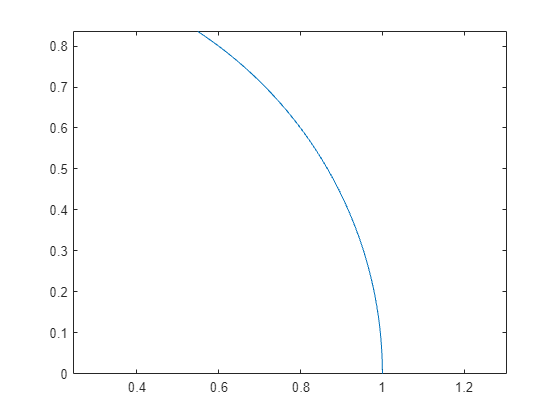

t = 0:0.01:1-0.01;
x = cos(t);
y = sin(t);


plot(x,y)
axis equal

Zad 3

Wygeneruj i przedstaw graficznie 3 okresy sygnałów. Amplituda A=+/- 1V, dla każdego wyznaczyć składową stałą i moc.

- Przebieg harmoniczny o częstotliwości f=1kHz

- Przebieg prostokątny o częstotliwości f=1kHz, wypełnieniu k=1/2 

- Przebieg piłokształtny o częstotliwości f=1kHz

- Przebieg trójkątny o częstotliwości f=1kHz

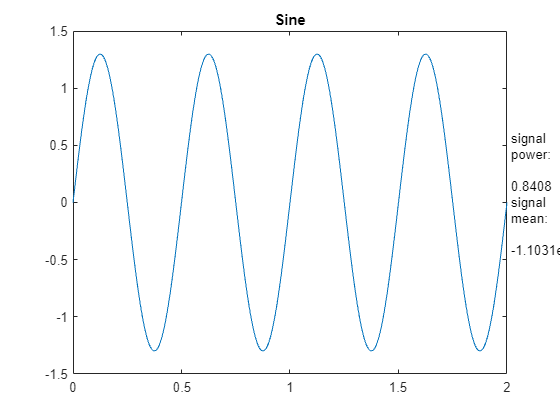

A = 1.3;
f =2;
k = 0.5;

w = 2*pi*f;
t = 0:0.01:2; %s

ad1 = A*sin(w*t);
power_ad1 = rms(ad1)^2;
mean_ad1 = mean(ad1);

plot(t, ad1);
title('Sine')
txt = ['signal power: ', string(power_ad1), 'signal mean: ', string(mean_ad1)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

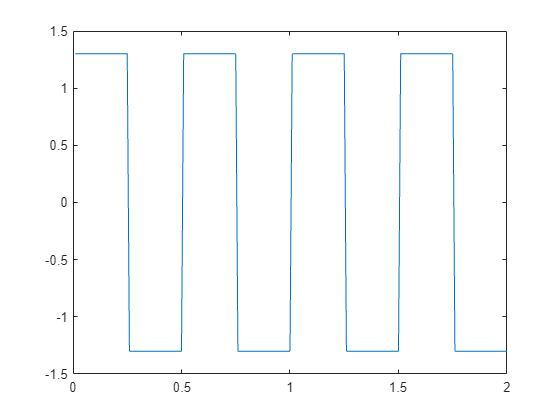

ad2 = A*(sin(w*t)./abs(sin(w*t)));
plot(t, ad2)